clear; clc;

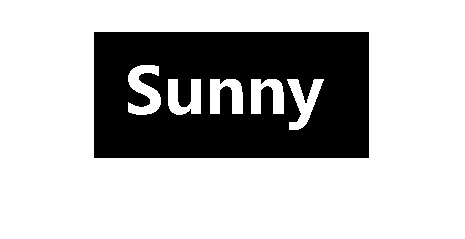

img = imread('sunny.png');
img = rgb2gray(img);
img_bw = imbinarize(img);
imshow(img_bw)

## dilate

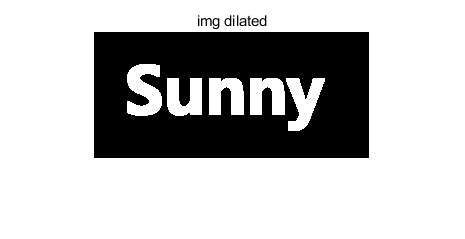

se1 = strel("square", 3);
img_di = imdilate(img_bw, se1);
imshow(img_di); title('img dilated')

## erode

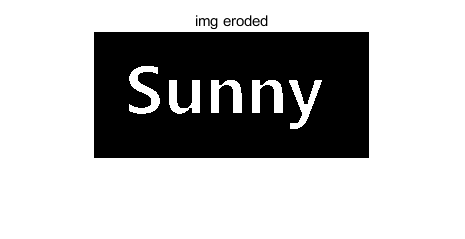

se2 = strel('square', 3);
img_er = imerode(img_bw, se2);
imshow(img_er); title('img eroded')

## opposite

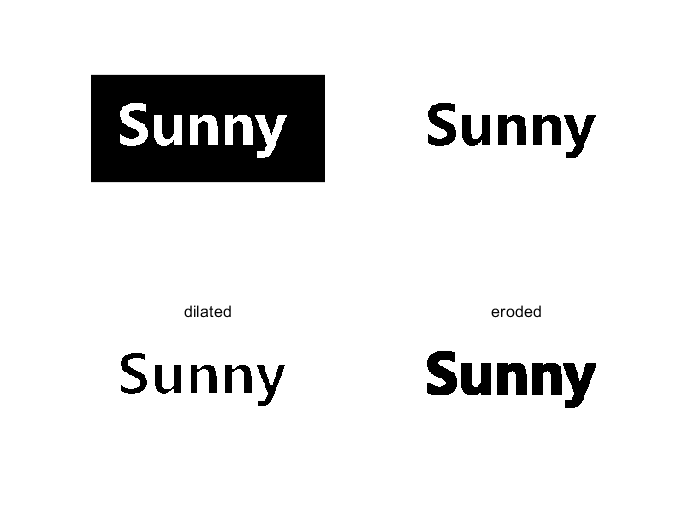

img_bw1 = 1 - img_bw;
img_di1 = imdilate(img_bw1, se1);
img_er1 = imerode(img_bw1, se2);
figure; 
subplot(2, 2, 1); imshow(img_bw);
subplot(2, 2, 2); imshow(img_bw1);
subplot(2, 2, 3); imshow(img_di1); title('dilated')
subplot(2, 2, 4); imshow(img_er1); title('eroded')

## open & close

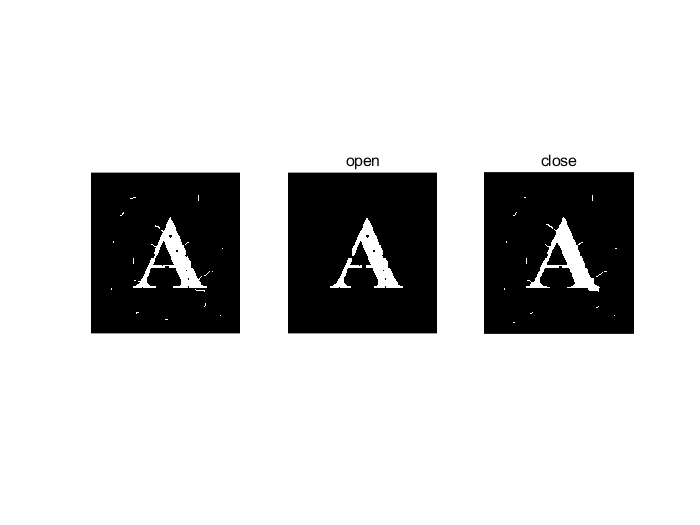

img = rgb2gray(imread('A.bmp'));
img_bw = imbinarize(img);
se = strel('square', 3);
img_op = imopen(img_bw, se);
img_cl = imclose(img_bw, se);
figure;
subplot(1, 3, 1); imshow(img_bw)
subplot(1, 3, 2); imshow(img_op); title('open')
subplot(1, 3, 3); imshow(img_cl); title('close')

## smooth

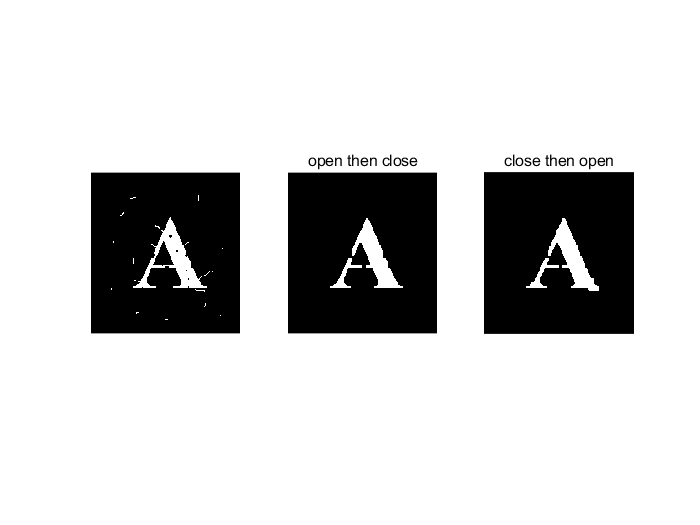

img_opcl = imclose(imopen(img_bw, se), se);
img_clop = imopen(imclose(img_bw, se), se);
figure;
subplot(1, 3, 1); imshow(img_bw)
subplot(1, 3, 2); imshow(img_opcl); title('open then close')
subplot(1, 3, 3); imshow(img_clop); title('close then open')

## edge detection

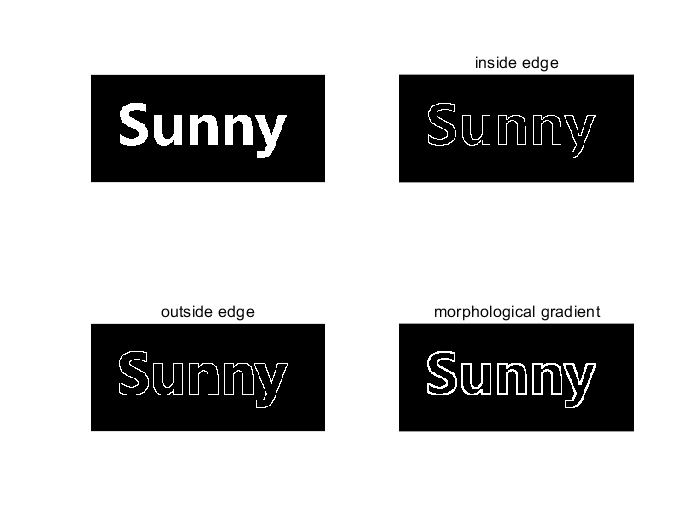

img = rgb2gray(imread('sunny.png'));
img_bw = imbinarize(img);
se = strel('square', 3);
edge1 = img_bw - imerode(img_bw, se);
edge2 = imdilate(img_bw, se) - img_bw;
edge3 = imdilate(img_bw, se) - imerode(img_bw, se);
figure; 
subplot(2, 2, 1); imshow(img_bw);
subplot(2, 2, 2); imshow(edge1); title('inside edge')
subplot(2, 2, 3); imshow(edge2); title('outside edge')
subplot(2, 2, 4); imshow(edge3); title('morphological gradient')

## fill

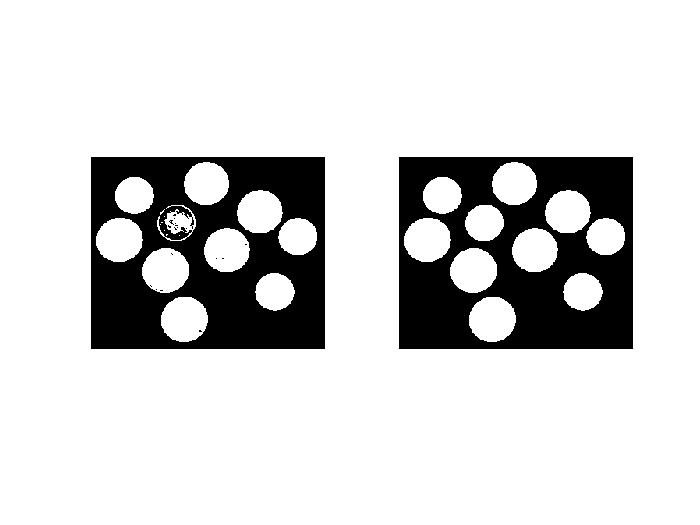

img_bw = imbinarize(imread('coins.png'));
img_bw_fill = imfill(img_bw, "holes");
figure;
subplot(1, 2, 1); imshow(img_bw)
subplot(1, 2, 2); imshow(img_bw_fill)

## hit & miss

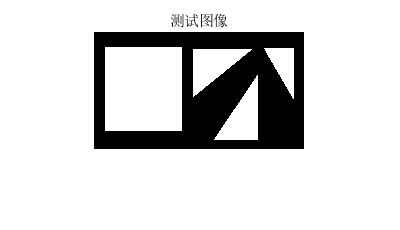

Image=imread('test.bmp');
BW=imbinarize(Image);                  
figure,imshow(BW),title('测试图像');

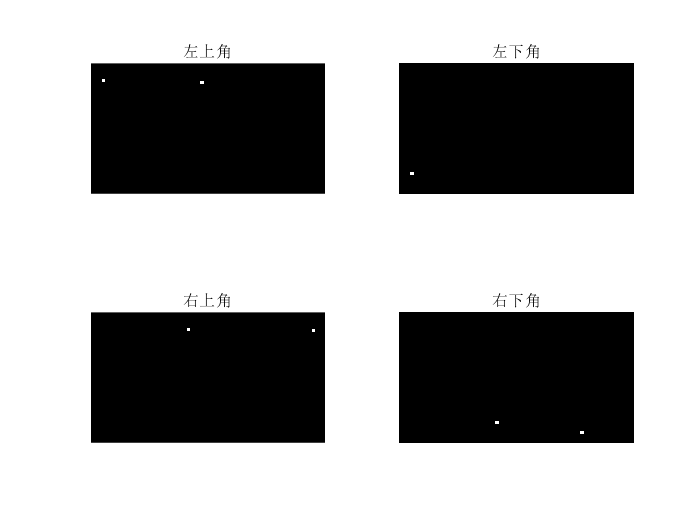


interval1=-ones(7); 
interval1(4:7,4:7)=interval1(4:7,4:7)*(-1);   %检测左上角的strel

interval2=-ones(7);
interval2(1:4,4:7)=interval2(1:4,4:7)*(-1);   %检测左下角的strel

interval3=-ones(7);
interval3(4:7,1:4)=interval3(4:7,1:4)*(-1);   %检测右上角的strel

interval4=-ones(7);
interval4(1:4,1:4)=interval4(1:4,1:4)*(-1);   %检测右下角的strel

SE=strel('square',3);
result1=imdilate(bwhitmiss(BW,interval1),SE);     
result2=imdilate(bwhitmiss(BW,interval2),SE); 
result3=imdilate(bwhitmiss(BW,interval3),SE); 
result4=imdilate(bwhitmiss(BW,interval4),SE); 
figure,
subplot(221),imshow(result1),title('左上角');
subplot(222),imshow(result2),title('左下角');
subplot(223),imshow(result3),title('右上角');
subplot(224),imshow(result4),title('右下角');

## thin

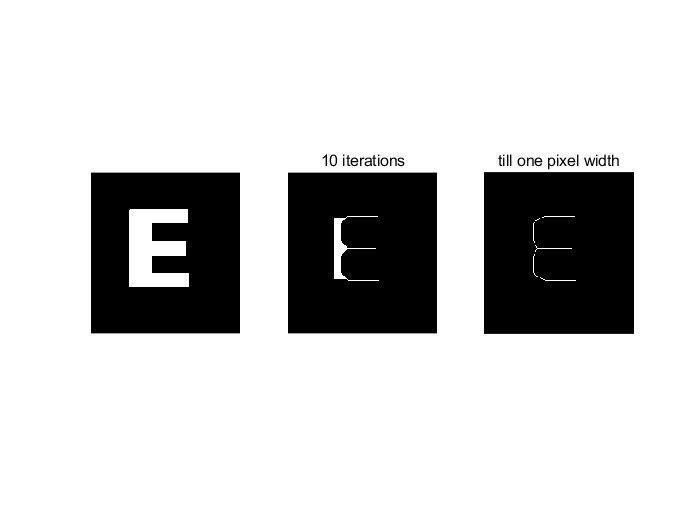

img_bw = imbinarize(rgb2gray(imread("E.bmp")));
img_thin1 = bwmorph(img_bw, 'thin', 10);
img_thin2 = bwmorph(img_bw, 'thin', inf);
figure;
subplot(1, 3, 1); imshow(img_bw)
subplot(1, 3, 2); imshow(img_thin1); title('10 iterations')
subplot(1, 3, 3); imshow(img_thin2); title('till one pixel width')

## gray img

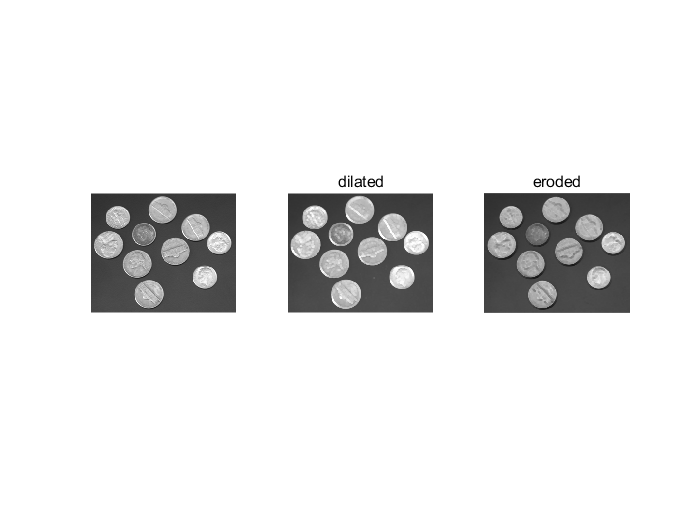

img = imread('coins.png');
se = strel("square", 3);
img_dil = imdilate(img, se);
img_ero = imerode(img, se);
figure;
subplot(1, 3, 1); imshow(img)
subplot(1, 3, 2); imshow(img_dil); title('dilated')
subplot(1, 3, 3); imshow(img_ero); title('eroded')

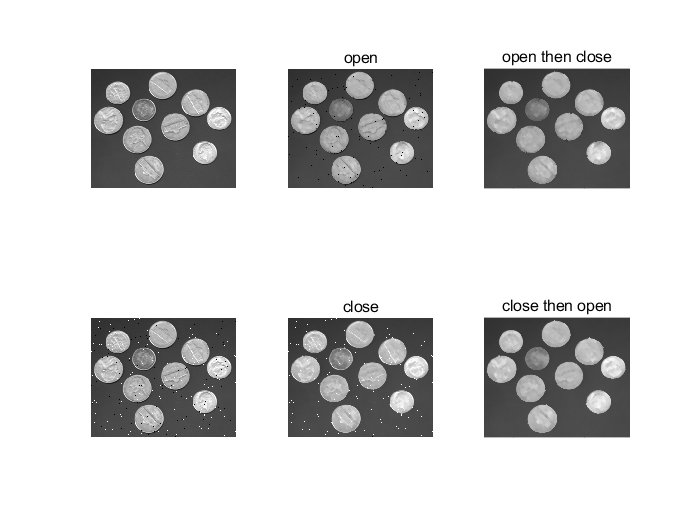

img_noise = imnoise(img, "salt & pepper", 0.01);
se = strel("disk", 2);
img_op = imopen(img_noise, se);
img_cl = imclose(img_noise, se);
img_opcl = imclose(imopen(img_noise, se), se);
img_clop = imopen(imclose(img_noise, se), se);
figure;
subplot(2, 3, 1); imshow(img)
subplot(2, 3, 4); imshow(img_noise)
subplot(2, 3, 2); imshow(img_op); title('open') 
subplot(2, 3, 5); imshow(img_cl); title('close')
subplot(2, 3, 3); imshow(img_opcl); title('open then close')
subplot(2, 3, 6); imshow(img_clop); title('close then open')

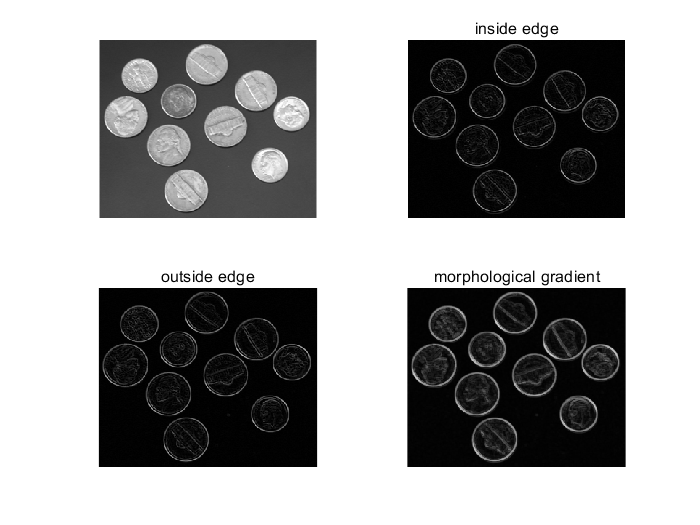

edge1 = img - imerode(img, se);
edge2 = imdilate(img, se) - img;
edge3 = imdilate(img, se) - imerode(img, se);
figure; 
subplot(2, 2, 1); imshow(img);
subplot(2, 2, 2); imshow(edge1); title('inside edge')
subplot(2, 2, 3); imshow(edge2); title('outside edge')
subplot(2, 2, 4); imshow(edge3); title('morphological gradient')

## top-hat & bottom-hat

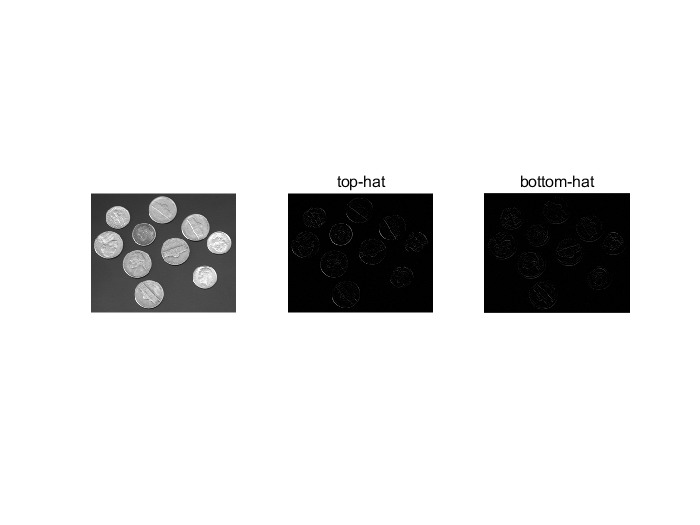

img_top = imtophat(img, se);
img_bot = imbothat(img, se);
figure;
subplot(1, 3, 1); imshow(img)
subplot(1, 3, 2); imshow(img_top); title('top-hat')
subplot(1, 3, 3); imshow(img_bot); title('bottom-hat')

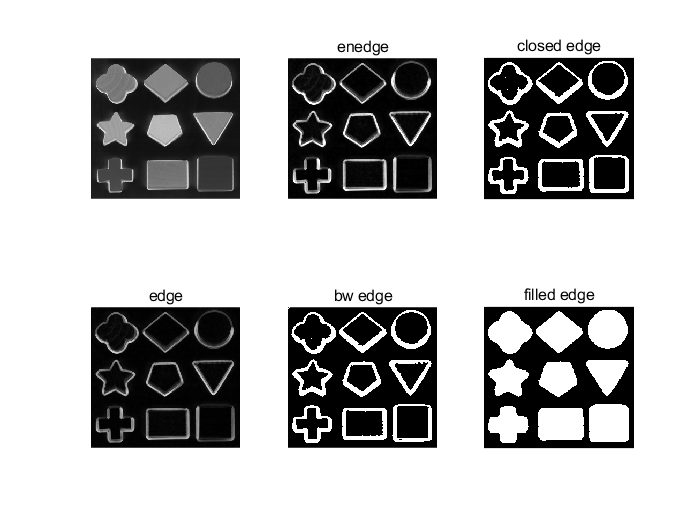

clear; clc;
img = imread('shape.png');
se = strel('disk', 2);
edge = imdilate(img, se) - imerode(img, se);
enedge = imadjust(edge);
bw = zeros(size(img));
bw(edge > 20) = 1;
bw1 = imclose(bw, se);
bw2 = imfill(bw1, "holes");
figure;
subplot(2, 3, 1); imshow(img)
subplot(2, 3, 4); imshow(edge); title('edge')
subplot(2, 3, 2); imshow(enedge); title('enedge') 
subplot(2, 3, 5); imshow(bw); title('bw edge')
subplot(2, 3, 3); imshow(bw1); title('closed edge')
subplot(2, 3, 6); imshow(bw2); title('filled edge')